# MAE 144 HW3

Brian Kong A16996735

# Question 1

Given: $\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+a_0 y\left(t\right)=b_o u\left(t-d\right)$, $a_0 =b_0 =0\ldotp 1s^{-1}$ for very small $\Delta t$.

Laplace transform: $\mathrm{sY}\left(s\right)+a_0 \;Y\left(s\right)=b_o \;U\left(s\right)\;e^{-\mathrm{ds}}$ when we set the IC's to be zero.

$\begin{array}{l}
\left(s+a_0 \right)\;Y\left(s\right)=b_o e^{-\textrm{ds}} \;U\left(s\right)\\
G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{b_0 e^{-\textrm{ds}} }{s+a_0 }
\end{array}$, and we convert $G\left(s\right)$ into the form of $G\left(s\right)=\frac{b_0 }{a_0 }\left(\frac{1}{1+a_0^{-1} s}\right)e^{-\mathrm{ds}}$ 

to generate the Bode plots $\log_{10} \;|G\left(j\omega \right)|$ and $\angle G\left(j\omega \right)$.

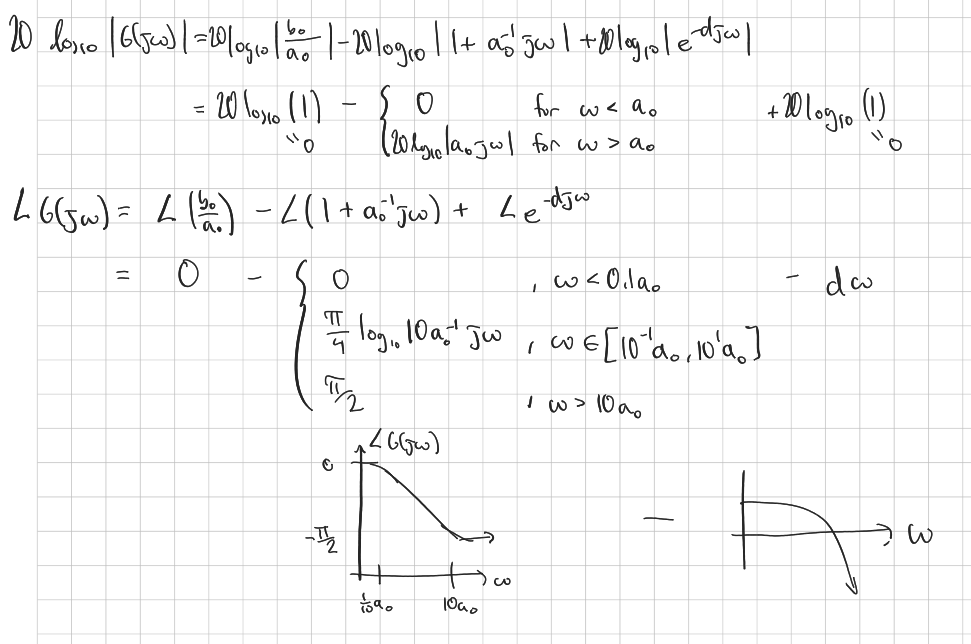

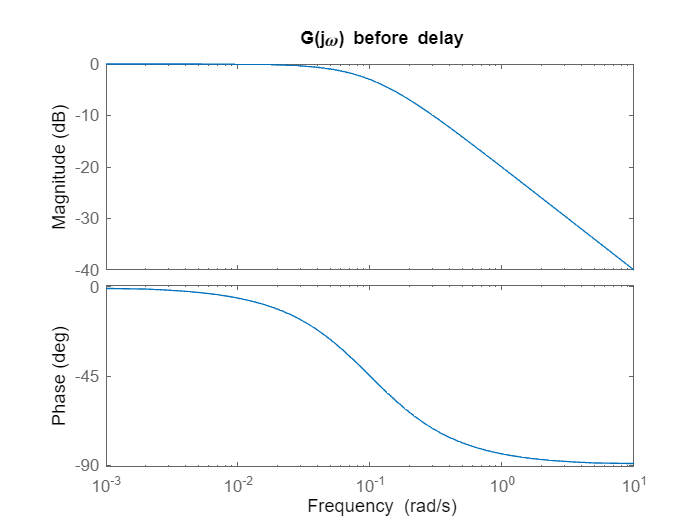

b0 = 0.1; a0=0.1;d = 6;
G_nodelay= tf(b0,[1 a0]);
G = tf(b0,[1 a0],'InputDelay',d);
figure;
bode(G_nodelay);    title("G(j\omega) before delay")

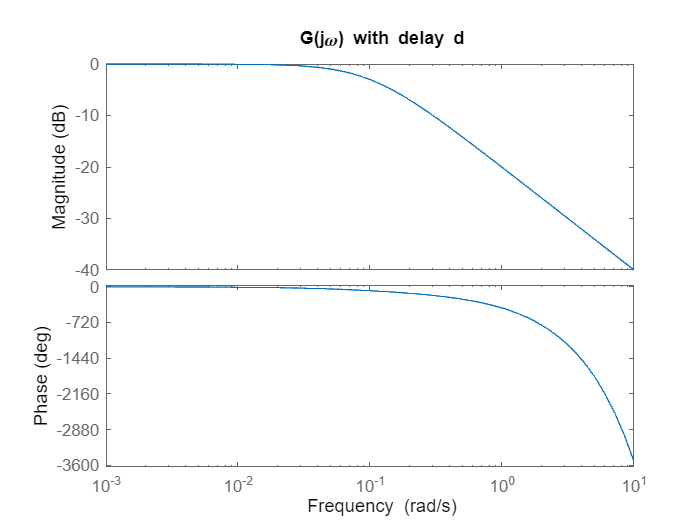

% bode_asymptotic(b0,[1 a0])
figure;
bode(G);    title("G(j\omega) with delay d")

# Question 2

We are now given a controller $D\left(s\right)=K_p \left(1+\frac{1}{T_I s}+T_D s\right)=K_p T_D \frac{\left(s^2 +\frac{s}{T_D }+\frac{1}{T_I T_D }\right)}{s}=\frac{K\left(s+z_+ \right)\left(s+z_- \right)}{s}$,

where $K_P =\alpha K_u \;,\;T_I =\beta T_u \;,T_D =\gamma T_u$, with $\left\lbrace \alpha ,\beta ,\gamma \right\rbrace =\left\lbrace 0\ldotp 6,\infty ,0\right\rbrace$which gives us 


$$K_P =0\ldotp 6\;K_u ,T_I =\infty ,T_D =0$$


This turns $D\left(s\right)=0\ldotp 6K_u \left(1+0+0s\right)=0\ldotp 6\;K_u$, where $K_u$ is the system is at the verge of closed loop stability.

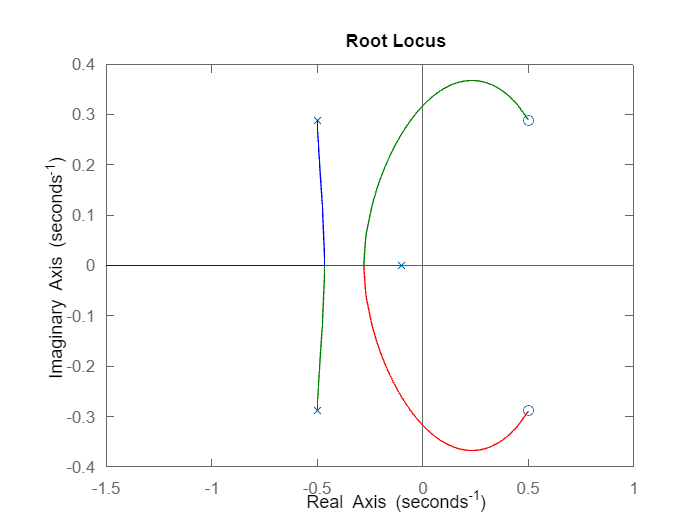

rlocus(pade(G,2));

The gain where the poles start to cross over (intersect with imaginary axis) is $K_u =3\ldotp 359$ $\therefore \;K_p =0\ldotp 6K_u =2\ldotp 015$

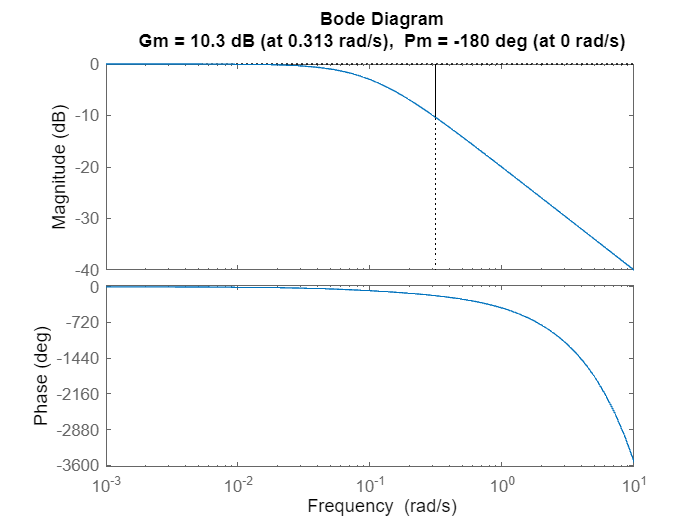

Kp = 0.6*2.015;
D = tf(Kp); L = D*G;
margin(G)

[Gm, Pm, omcg, omcp]=margin(G)

Gm = 3.2887

Pm = -180

omcg = 0.3133

omcp = 0

From this we get that $\omega_p =0\ldotp 3133\mathrm{rad}/s$ and $\mathrm{GM}=3\ldotp 2887$ for when $\angle L\left(j\omega_p \right)=-{180}^{\circ }$ and $|L\left(j\omega_p \right)|$.

With actual magnitudes, it'd be $\mathrm{GM}=L\left(j\;\omega_p \right)-1$, but with dB the -1 becomes a zero. To get our GM from the bode plot, we simply convert the value from dB to actual magnitude.

# Question 3

## a)

By dialing $\beta$ down from infinity, we increase the effects of the derivative portion in our PID controller.

This introduces a dampening effect as it starts accounting for the rate of change towards a reference, starting to dampen oscillations.

From the perspective of frequencies, we lower the crossover frequencies for which the controller starts amplifying frequencies from the high end (from the trait of $T_D s$) and introduces a phase lead above the rest of the frequency range below it.

## b)

By dialing $\gamma$ up from 0, we increase the effects of the integral portion of the PID controller.

This helps correct steady state error and reach a set point. This amplifies frequencies lower than its crossover frequency,

and introduces a phase lag compared to frequencies above it.

This can cause a problem with integrator windup, where the controller remains dominated by the integral portion for a short interval of time.

# Question 4

## a

$K_P =\alpha K_u \;,\;T_I =\beta T_u \;,T_D =\gamma T_u$, $\left\lbrace \alpha ,\beta ,\gamma \right\rbrace =\left\lbrace 0\ldotp 6,0\ldotp 5,0\ldotp 125\right\rbrace$

K_u = 3.359; % from previous
K_p = 0.6*K_u; 
om_p = omcg; T_u = 1/om_p; T_I = 0.5*T_u; T_D = 0.125*T_u;
om_I = 1/T_I, om_D = 1/T_D

om_I = 0.6266

om_D = 2.5064


$$D\left(s\right)=K_p T_D \frac{\left(s^2 +\frac{s}{T_D }+\frac{1}{T_I T_D }\right)}{s}$$


D = K_p*T_D*tf([1 1/T_D 1/(T_I*T_D)],[1 0])

D =
 
  0.8041 s^2 + 2.015 s + 1.263
  ----------------------------
               s
 
Continuous-time transfer function.
Model Properties


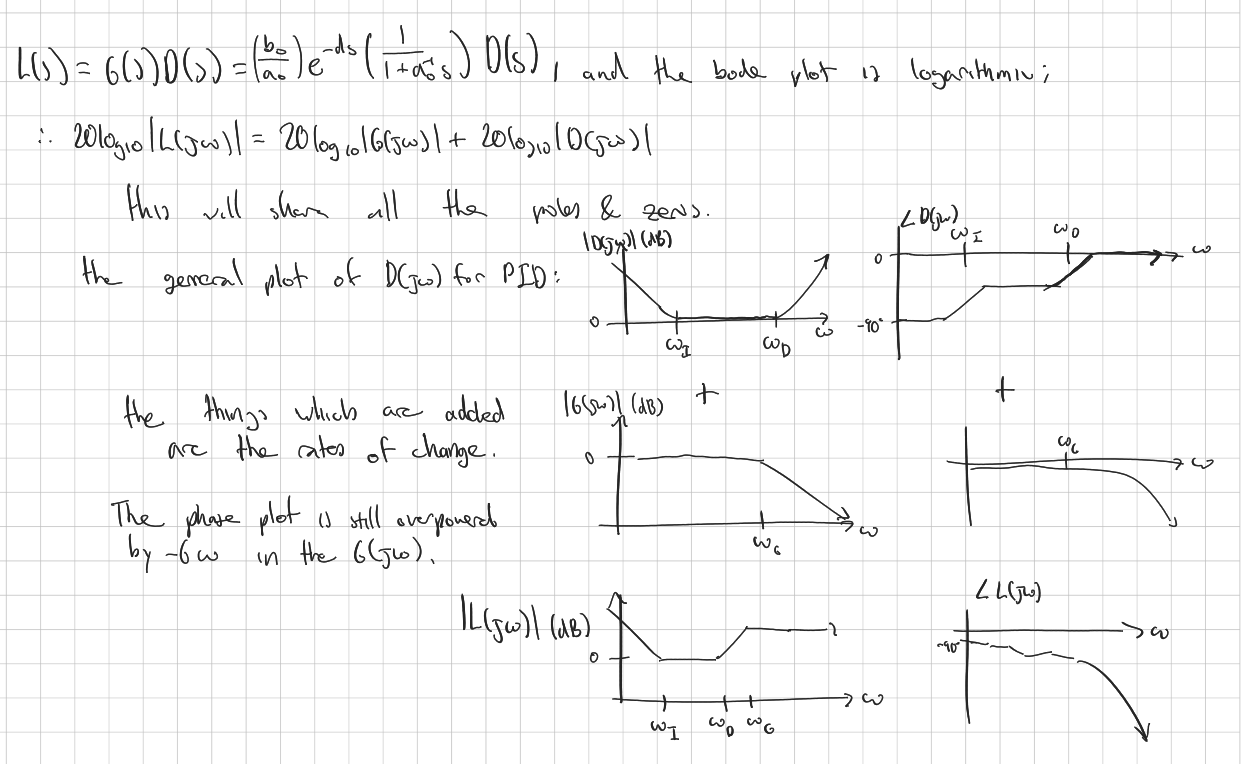

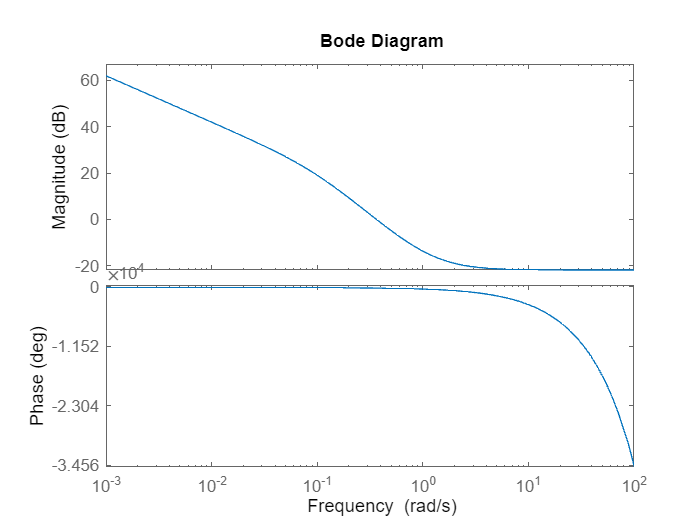

%In code:
L = G*D;
bode(L)

The hand drawing is not accurate with the placement of the crossover frequencies, but we can still see that the phase is dominated by the delay, 

and past the $\omega_D$ and $\omega_g$, the rate of change in the magnitude from the pole in $G\left(s\right)$ is cancelled by the derivative controller, resulting in a magnitude plot that is level past all the crossover frequencies.

## b


$$y\left(t=0\right)=20,x=\left\lbrace \begin{array}{ll}
35 & t\in \left\lbrack 0,1\right\rbrack \\
45 & t\in \left\lbrack 1,4\right\rbrack \\
20 & t\in \left\lbrack 4,5\right\rbrack 
\end{array}\right.$$


Assuming the system is stable, it would have a response like the following:

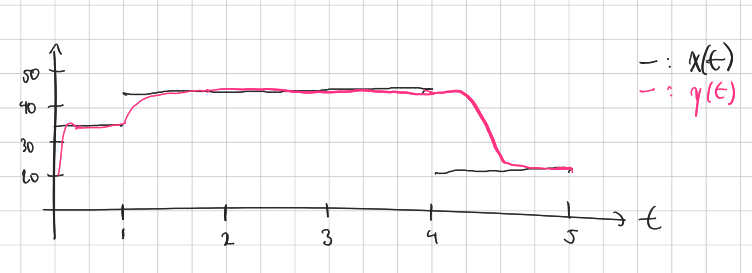

The transitions between the temperature changes would have extreme oscillations before settling to the desired values as a result of the delays, and the temperature drop after maintaining the higher temperature for 3 hours would result in an integrator windup, where the controller is saturated and takes a while to start responding as we desire and fall & settle to our target temperature.

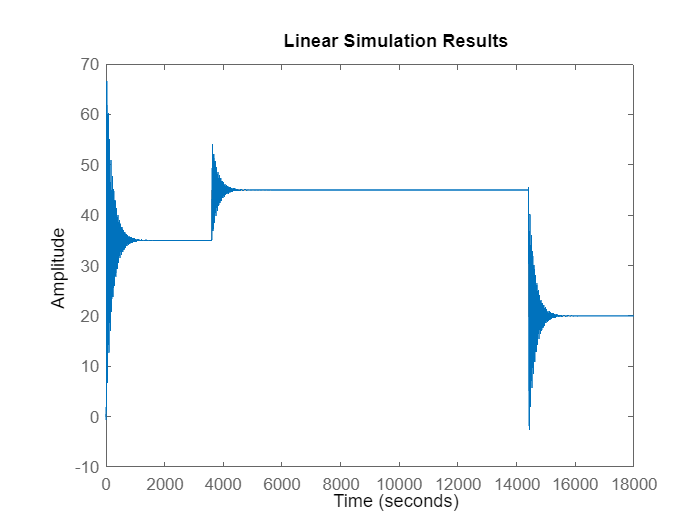

K_u = 3.359; % from previous
K_p = 0.1*K_u; 
om_p = omcg; T_u = 1/om_p; T_I = 0.5*T_u; T_D = 0.125*T_u;
om_I = 1/T_I; om_D = 1/T_D;
D = K_p*T_D*tf([1 1/T_D 1/(T_I*T_D)],[1 0]); L = G*D; T = L/(1+L);
t = 0:5*3600;
x = [35 * ones(size(t(t <= 1*3600))), 45 * ones(size(t(t > 1*3600 & t <= 4*3600))), 20 * ones(size(t(t > 4*3600 & t <= 5*3600)))];
lsimplot(pade(T,2),x,t);

There are a few flaws with the simulation: the starting temperature here is 0 because the simulation does not like nonzero initial conditions for a state space with a defined delay. However this still portrays the very unstable nature of our system in addition to how it demands for water temperature our system can not provide. To make matters worse, this simulation is with the proportional tuned down to 0.1 instead of 0.6 of K_u. This is all to say the closed loop (CL) system is not stable with the original controller, and is not very functional either.

## c

With the same assumptions as part b, we would see a similar response over time, but it would take substantially longer for it to reach values slightly lower than our target.

# Question 5

## a

There are two major issues with using such a PID controller:

- The integral component can result in integrator windup where the controller is saturated as a result of having a nonzero $e\left(t\right)$ inside the feedback loop, which results in an extremely scaled value of the controller $u\left(t\right)$. This results in an issue where the controller's responsiveness is delayed as it takes too long to decrease to the actual control we try to apply, which can lead to CL instability.

- The derivative component inherently amplifies high frequencies, and as a result can amplify the effect of high frequency noise, and waste the controller's energy as it chases after correcting amplified noise.

Instead, I would rather use a lead-lag controller with the added zeros and poles to make the CL system proper. This type of controller offer a safer method of adding the integral or derivative behavior to the controller without having the issues of integrator windup or high frequency noise amplification, because unlike the PID controller, lead-lag controllers target specific ranges for the integral and derivative aspects of the controller, and have a finite amount of gain for them. 

## b

First of all, I would increase the temperature range that can be actuated by the controller, changing the upper temperature limit to something higher like 70 C, somewhere hot enough to get stronger controls but not too much to become a major safety hazard.

Secondly, I would try to find a method of reducing the delay of the system, as 6 seconds is a bit extreme. One suggestion could be to shorten the length of the pipe from the valve which according to the definition for the delay we account for in the system, represents the time it takes for the water to flow from the valve to the pipe outlet.

Another method to reduce this delay is increasing the pressures for which the shower operates on.

# Question 6

## a

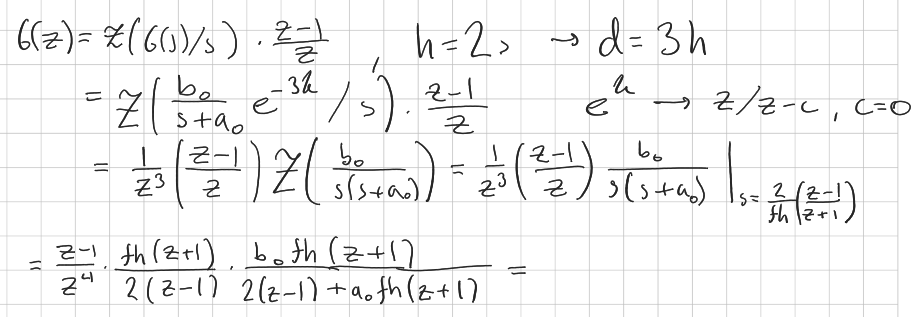

syms s z b0 a0 f h
G_ct = b0/(a0+s);
G_DT = 1/z^3*subs(G_ct/s,s,2/(f*h)*(z-1)/(z+1))*(z-1)/z

$$G\_DT = \frac{b_{0}\,f\,h\,\left(z+1\right)}{2\,z^{4}\,\left(a_{0}+\frac{2\,\left(z-1\right)}{f\,h\,\left(z+1\right)}\right)}$$

And we simplify to get this as our $G\left(z\right):$

G_DT=collect(simplify(G_DT))

$$G\_DT = \frac{\left(b_{0}\,f^{2}\,h^{2}\right)\,z^{2}+\left(2\,b_{0}\,f^{2}\,h^{2}\right)\,z+b_{0}\,f^{2}\,h^{2}}{\left(2\,a_{0}\,f\,h+4\right)\,z^{5}+\left(2\,a_{0}\,f\,h-4\right)\,z^{4}}$$

[num, den]= numden(G_DT);
G_DTTF= RR_tf(coeffs(num,z),flip(coeffs(den,z)))*RR_tf(1,[1 0 0 0 0])

G_DTTF =   RR_tf with properties:
num:[(b0*f^2*h^2)/(2*a0*f*h + 4), (b0*f^2*h^2)/(a0*f*h + 2), (b0*f^2*h^2)/(2*a0*f*h + 4)]
den:[1, (a0*f*h - 2)/(a0*f*h + 2), 0, 0, 0, 0]
Continuous-time transfer function
  m=2, n=5, n_r=n-m=3, strictly proper, K=(b0*f^2*h^2)/(2*a0*f*h + 4)
  z:[-1, -1]
  p:[0, 0, 0, 0, -(a0*f*h - 2)/(a0*f*h + 2)]

We can observe that the zeros are in the LHP, and as such, the system $G\left(z\right)$ is minimum phase.

The system is also stable for $a_0 f\;h\;>2$, which is the requirement for the pole to be in the LHP.

The degree of our denominator is greater than the numerator, so we can also say that $G\left(z\right)$ is causal.

## b

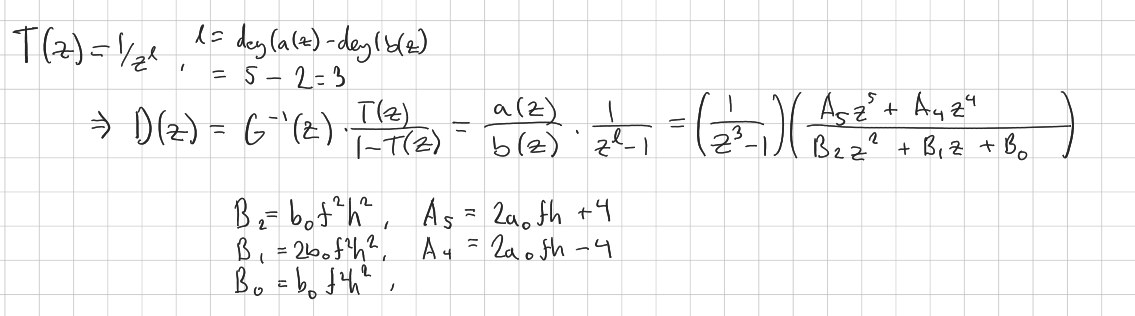

This is called a minimal-time deadbeat, which results in the fastest possible transfer function to completely settle the output for a DT system.

However, even if $y_k$ settles, $u_k$ is not restricted to such, and results in control oscillations. I would also expect some ripple for our given system, and a simple proposal to reduce the said ripple would have a greater value of $h$ (preferrably a factor of our delay), or using a ripple-free deadbeat controller. This controller wouldn't be the fastest to reach the goal and is non-minimum phase. However, it is designed to allow the zeros of G appear in the numerator of our $T\left(z\right)$ and as a result, they don't show up in the sensitivity function $S_u \left(z\right)$ for the control, which allows both the output and control to settle completely $l$ timesteps after a step input.

## c

I expect the DT controller to run into issues where the control is trying to send temperatures that exceed or fall below the boundaries of our control inputs which would be outside of 10 or 50 C. This would be an issue for temperatures near said boundaries, and also an issue for when there are temperature jumps that span more than half the temperature range.

# Extra Credit